clear
M1 = readmatrix("寻峰2.xlsx");
ch = M1(:,2);
dd = 9.26e8;
deltaE = ch(1) - ch

deltaE = 1.0e+03 *

         0
    0.2885
    0.5922
    0.9097
    1.2453
    1.6059
    1.9975
    2.3988


deltaX = deltaE/dd*1e7

deltaX =          0
    3.1158
    6.3950
    9.8241
   13.4479
   17.3419
   21.5717
   25.9046


NN = 0:7;
ff = fit(NN',deltaX,'poly1')

ff =      线性模型 Poly1:
     ff(x) = p1*x + p2
     系数(置信边界为 95%):
       p1 =       3.691  (3.471, 3.912)
       p2 =     -0.7197  (-1.641, 0.2017)

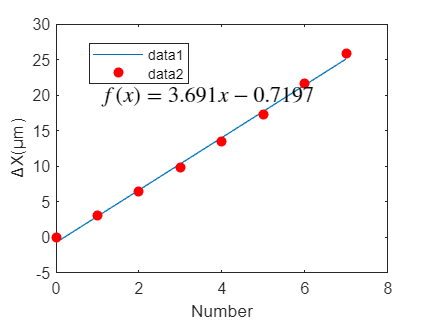

hold on
plot(NN,ff(NN))
scatter(NN,deltaX,'red','filled')
legend("Position",[0.2356,0.75817,0.17679,0.086905])
box on
ylabel('ΔX(μm)')
xlabel('Number')
text(1,20,'$f(x) = 3.691x-0.7197$','Interpreter','latex','FontSize',13)